# DSP Lab 02

# Working with discrete 1D signals

## 1. Objective

Students should gain knowledge on some of the basic Matlab functions for handling discrete unidimensional signals

## 2. Theoretical aspects

### 2.1. Plotting data signals (vectors)

Recall from Lab01 how to make a plot:

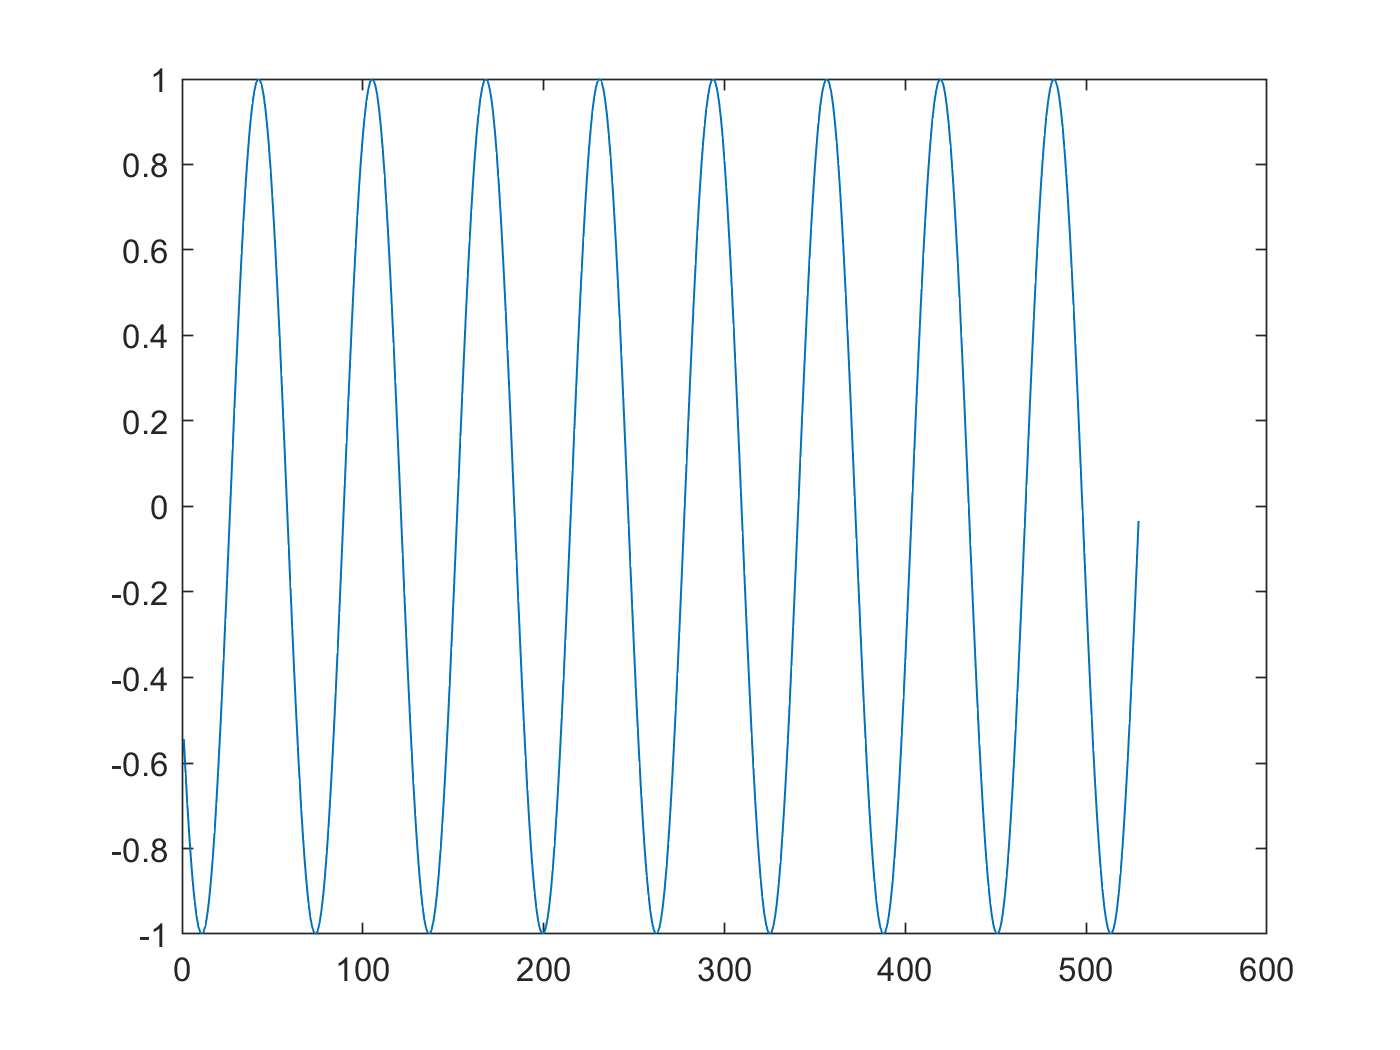

A = 10:0.1:(20*pi);   % A vector going from 0 to 4pi
X = sin(A);           % sin() is applied to every element of A
plot(X)       % Use plot() to display values like a continous function

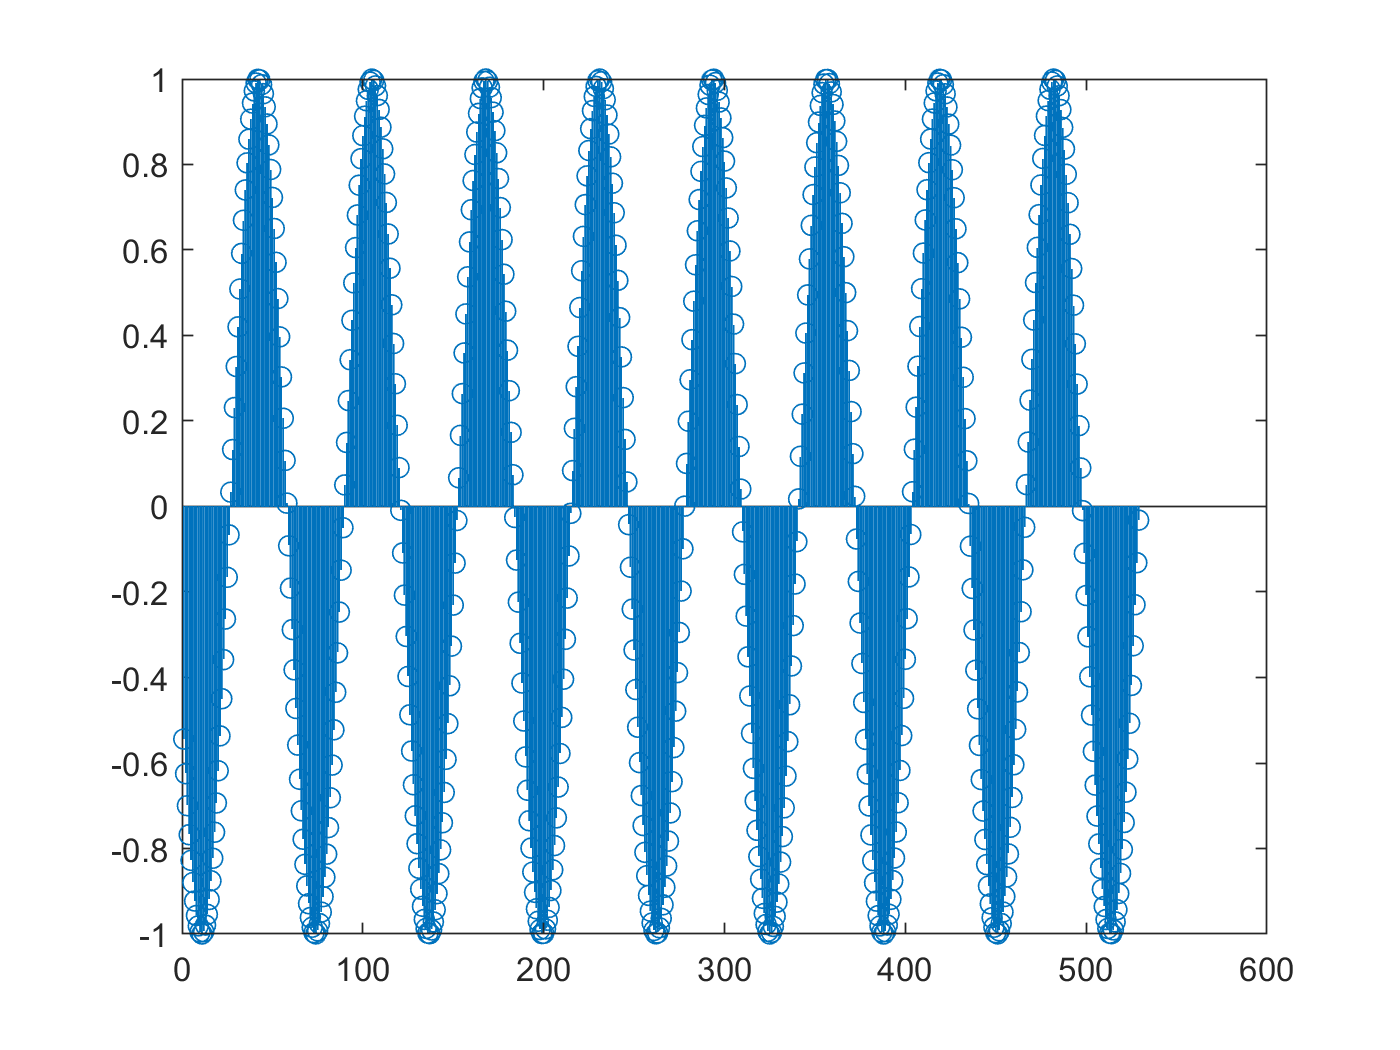

stem(X)       % Use stem() to display values with vertical sticks, like a discrete signal

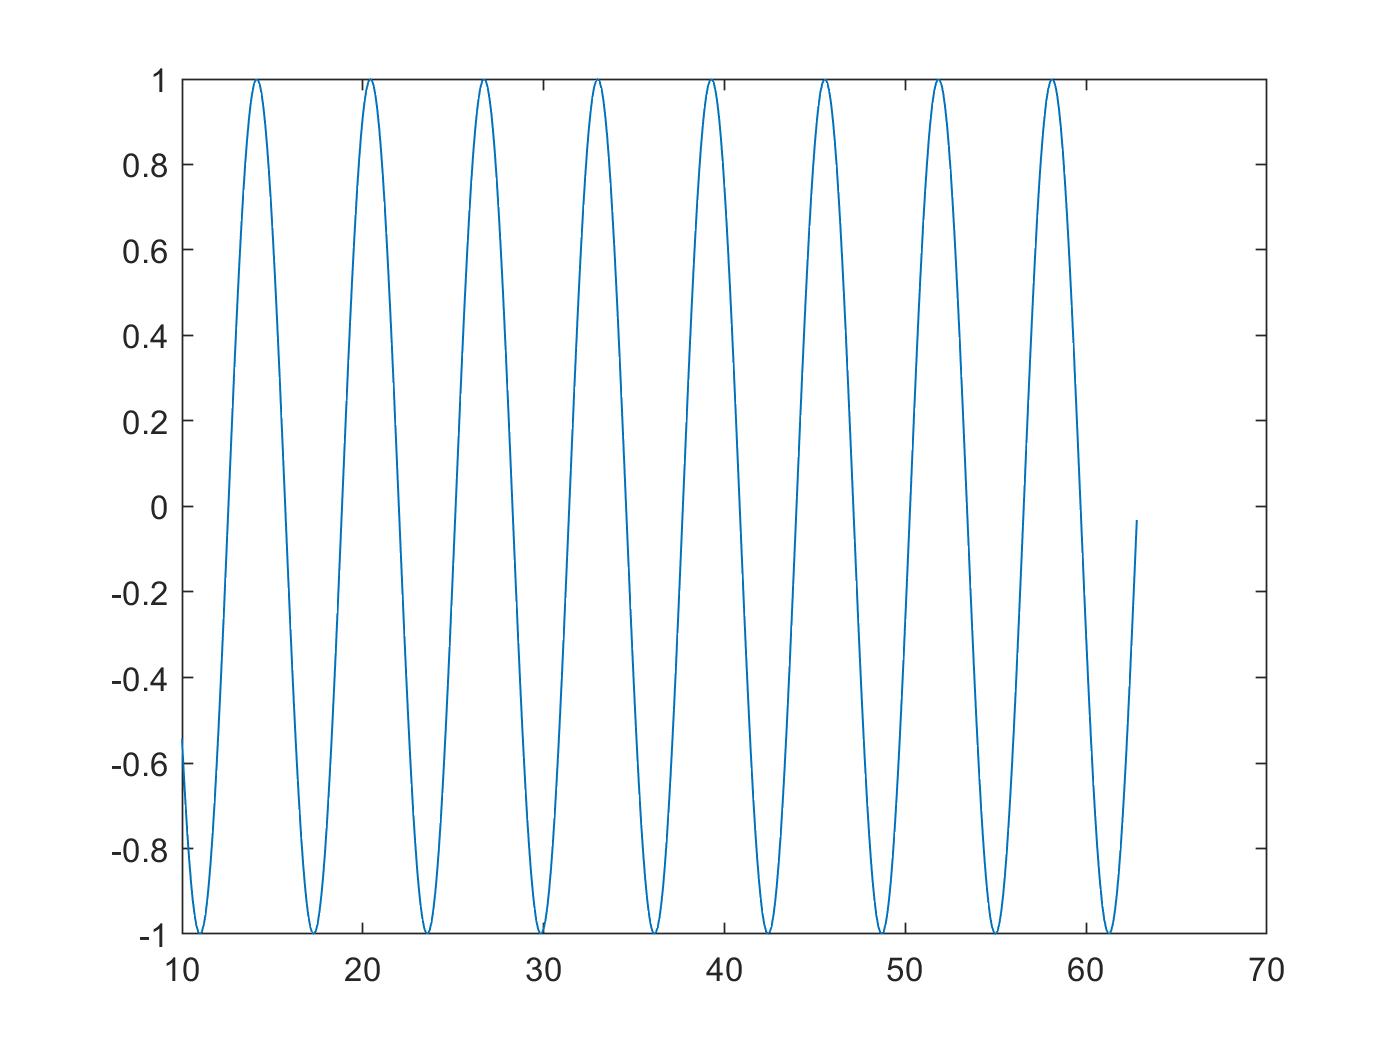

plot(A, X)    % Like plot(X), but puts values in A on the Ox axis

Here are some more advances options. You can read more details in the Help of the function `plot()`.

We can customize the line color ('r', 'g', 'm' etc.) or the line style ('--'  ,   ':'  ,   '-.'  )

plot(A, X, 'r-.');   % red color, dashed line

Unrecognized function or variable 'A'.

We can plot multiple signals on a same figure by putting them as **columns** in a matrix and then run `plot()` on the matrix.

t = 0:0.01:10;        % time going from 0 to 10 in small steps
x1 = sin(2*pi*0.2*t)  % sin signal

x1 =          0    0.0126    0.0251    0.0377    0.0502    0.0628    0.0753    0.0879    0.1004    0.1129    0.1253    0.1378    0.1502    0.1626    0.1750    0.1874    0.1997    0.2120    0.2243    0.2365    0.2487    0.2608    0.2730    0.2850    0.2970    0.3090    0.3209    0.3328    0.3446    0.3564    0.3681    0.3798    0.3914    0.4029    0.4144    0.4258    0.4371    0.4484    0.4596    0.4707    0.4818    0.4927    0.5036    0.5144    0.5252    0.5358    0.5464    0.5569    0.5673    0.5776


x2 = cos(2*pi*0.2*t)  % cos signal

x2 =     1.0000    0.9999    0.9997    0.9993    0.9987    0.9980    0.9972    0.9961    0.9950    0.9936    0.9921    0.9905    0.9887    0.9867    0.9846    0.9823    0.9799    0.9773    0.9745    0.9716    0.9686    0.9654    0.9620    0.9585    0.9549    0.9511    0.9471    0.9430    0.9387    0.9343    0.9298    0.9251    0.9202    0.9152    0.9101    0.9048    0.8994    0.8938    0.8881    0.8823    0.8763    0.8702    0.8639    0.8575    0.8510    0.8443    0.8375    0.8306    0.8235    0.8163


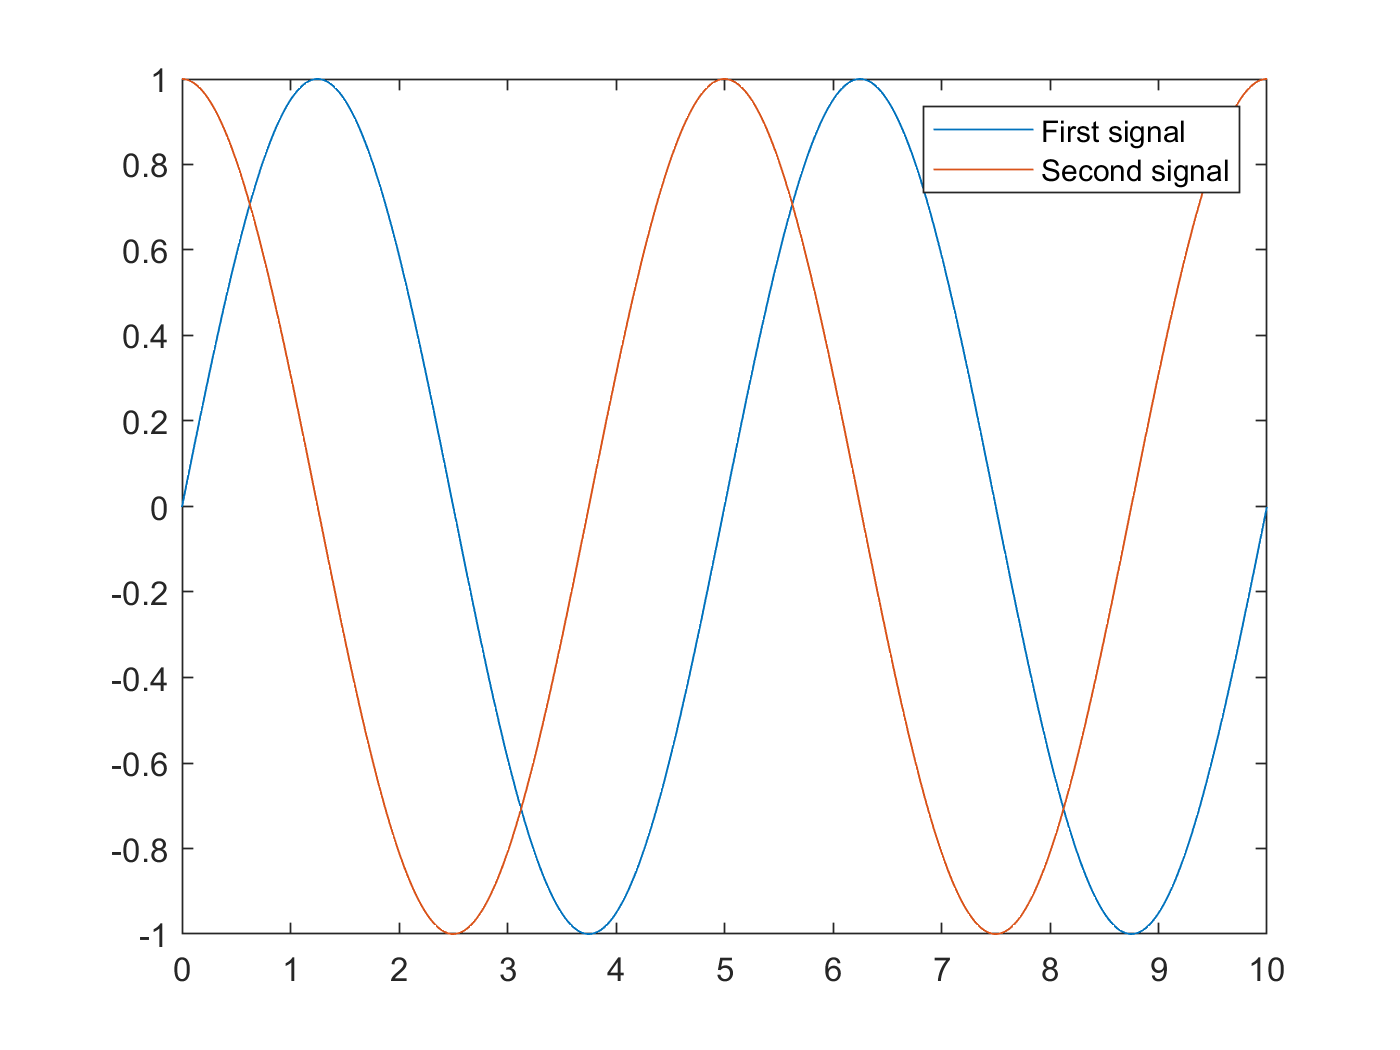

plot(t, [x1' x2'])    % plot both signals
legend('First signal', 'Second signal');  % Display legend

The key trick is on line 4:    `[x1'  x2']`

- `x1` and `x2` are row vectors (check their size in Workspace)

- We transpose them with ' , therefore x1' and x2' are column vectors

- The two column vectors are concatenated horizontally by placing them inside square brackets [ ... ], which means they form a matrix with two columns

- Thus,  `[x1'  x2']` means "x1 and x2 transposed and then concatenated horizontally"

### 2.2. Loading / saving data from .mat files

Data from Matlab Workspace can be saved in data files, and loaded later. The default extension for these files is `.mat`

Save all the current Workspace data in a data file:

save('mydata.mat');

Now you can clear the workspace, or restart Matlab, and then load the data back:

load('mydata.mat')

There are options to save/load only some variables. More details if you read the Help on `save()` or `load()` functions.

### 2.3. Working with audio data

You will need to download the file `FireOrchestra.mp4` from the repository.

A discrete audio signal is simply a vector with many, many sample values. If it is a stereo signal, it contains two signals, for the Left and Right channels. Various audio file types store the data in different compressed ways, but reading and decompressing the file always produces the samples.

Matlab has functions to read various audio formats and produce the samples. We can work on the samples to implement various digital signal processing techniques.

We can import signals from audio files with the `audioread()` function.

Read the docs first to see how the function is called.

Don't forget the ; at the end. There may be millions of samples in the file, and we don't want to see them all in the Command Window.

[x, Fs] = audioread('FireOrchestra.m4a');  % Read data from Kaliba.mp3
%  x = the sample vector(s)
% Fs = the sampling frequency

For small teaching examples, it is often easier to work with smaller signals, a few seconds long instead of minutes. We can tell `audioread()` to load only a few secons of data:

 % Read only the first 300000 samples (from 1 to 300000)
[x, Fs] = audioread('FireOrchestra.m4a', [1 300000]);

We can do whatever processing we want on the data. 

When we want to play some vector on the audio output, we use the function `sound()`, giving it the data and the sampling frequency.

**Note**: Once playback is started, it cannot be stopped! (at least not with the `sound()` function). Make sure you're not playing a 1h long audio file.

sound(x, Fs);  % Make sure you open your speakers

### 2.4. Applying windows to signals

TODO

    - concept of window

    - Hann window in Matlab

## 3. Exercises

1. Plot on the same figure the signals $\sin(2 \pi f t + \frac{\pi}{4})
$ and $\cos(2 \pi f t + \frac{\pi}{8})$, with $f = 0.3$and time $t \in [0, 10]$.

2. Save the vectors above in the file `mysave.mat`. Clear the variables from the Matlab workspace, then load them back from `mysave.mat`.

3. Load the first 10 seconds of the audio file `Kalimba.mp3` in the Matlab workspace (*Hint: the sampling frequency is probably the common audio one: *$F_s=44100 Hz$*. You can always check this once you loaded th data*).

- Play it through the computer's audio device

- Change the sampling frequency to half the correct value, and play again. How will the sound be changed?

- Amplify the sound by multiplying the data by 4. Play the sound and observe the difference.

- Swap the left and right channels (it's a stereo file).

- Think and implement a fading-in and fading-out on the audio. 

4. Generate a long signal (20000 elements) looking like $[1, -1, 1, -1, ...]$ and play it using $F_s = 8000$. 

- What signal do you hear? 

- What is it's frequency?

5. Generate and play a 3 seconds long sinusoidal signal with frequency $f=2000Hz$ considering a sampling frequency $F_s = 8000Hz$

## 4. Final questions

1. TBD